t = 0:0.001:10

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


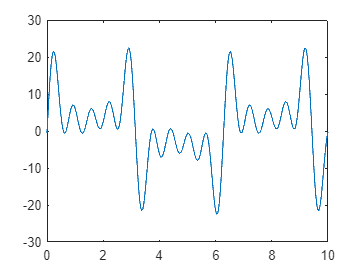


N = 10; % Number of coefficients
a = zeros(1, N);
b = zeros(1, N);
for n = 1:N
    a(n) = -2*sin(n*pi/2)/(n*pi); % Compute coefficient a_n
    b(n) = 3-3*cos(n*pi); % Compute coefficient b_n
end

% Reconstruct the Fourier series
F = zeros(size(t)); % Initialize the Fourier series
for n = 1:N
    F = F + a(n)*cos(n*t) + b(n)*sin(n*t); % Add each term of the series
end
plot(t, F)

t = -10:0.01:10

t =   -10.0000   -9.9900   -9.9800   -9.9700   -9.9600   -9.9500   -9.9400   -9.9300   -9.9200   -9.9100   -9.9000   -9.8900   -9.8800   -9.8700   -9.8600   -9.8500   -9.8400   -9.8300   -9.8200   -9.8100   -9.8000   -9.7900   -9.7800   -9.7700   -9.7600   -9.7500   -9.7400   -9.7300   -9.7200   -9.7100   -9.7000   -9.6900   -9.6800   -9.6700   -9.6600   -9.6500   -9.6400   -9.6300   -9.6200   -9.6100   -9.6000   -9.5900   -9.5800   -9.5700   -9.5600   -9.5500   -9.5400   -9.5300   -9.5200   -9.5100


Ts = 1/10000;
f1 = 4*sinc(4*t)

f1 =    -0.0000   -0.0040   -0.0079   -0.0118   -0.0154   -0.0188   -0.0219   -0.0247   -0.0271   -0.0291   -0.0306   -0.0316   -0.0322   -0.0322   -0.0317   -0.0307   -0.0293   -0.0273   -0.0250   -0.0222   -0.0191   -0.0157   -0.0120   -0.0081   -0.0041    0.0000    0.0041    0.0081    0.0121    0.0158    0.0193    0.0225    0.0253    0.0278    0.0298    0.0314    0.0324    0.0330    0.0330    0.0325    0.0315    0.0300    0.0281    0.0256    0.0228    0.0196    0.0161    0.0123    0.0083    0.0042


f2 = (sinc(t)).^2

f2 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011    0.0011


f = f1

f =    -0.0000   -0.0040   -0.0079   -0.0118   -0.0154   -0.0188   -0.0219   -0.0247   -0.0271   -0.0291   -0.0306   -0.0316   -0.0322   -0.0322   -0.0317   -0.0307   -0.0293   -0.0273   -0.0250   -0.0222   -0.0191   -0.0157   -0.0120   -0.0081   -0.0041    0.0000    0.0041    0.0081    0.0121    0.0158    0.0193    0.0225    0.0253    0.0278    0.0298    0.0314    0.0324    0.0330    0.0330    0.0325    0.0315    0.0300    0.0281    0.0256    0.0228    0.0196    0.0161    0.0123    0.0083    0.0042


F = fft(f)

F = 1.0e+02 *

   0.9949 + 0.0000i  -1.0051 - 0.0016i   0.9949 + 0.0031i  -1.0051 - 0.0047i   0.9949 + 0.0062i  -1.0051 - 0.0079i   0.9948 + 0.0094i  -1.0052 - 0.0110i   0.9947 + 0.0125i  -1.0052 - 0.0142i   0.9945 + 0.0156i  -1.0053 - 0.0174i   0.9943 + 0.0187i  -1.0054 - 0.0205i   0.9940 + 0.0219i  -1.0056 - 0.0237i   0.9937 + 0.0250i  -1.0058 - 0.0269i   0.9933 + 0.0281i  -1.0061 - 0.0300i   0.9928 + 0.0312i  -1.0064 - 0.0332i   0.9922 + 0.0343i  -1.0069 - 0.0364i   0.9914 + 0.0374i  -1.0075 - 0.0396i   0.9904 + 0.0405i  -1.0084 - 0.0428i   0.9891 + 0.0435i  -1.0096 - 0.0460i   0.9874 + 0.0465i  -1.0114 - 0.0493i   0.9847 + 0.0495i  -1.0144 - 0.0526i   0.9805 + 0.0524i  -1.0199 - 0.0561i   0.9721 + 0.0550i  -1.0326 - 0.0601i   0.9485 + 0.0567i  -1.0885 - 0.0667i   0.5177 + 0.0326i   0.0879 + 0.0057i   0.0471 + 0.0031i   0.0317 + 0.0021i   0.0237 + 0.0016i   0.0188 + 0.0013i   0.0155 + 0.0011i   0.0132 + 0.0010i   0.0114 + 0.0009i   0.0100 + 0.0008i


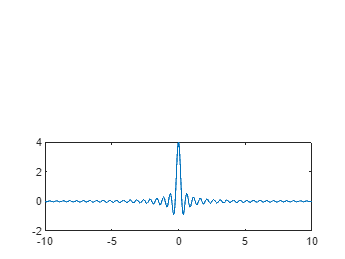


plot(t, f)

% Onda cuadrada
t = 0:0.01:8

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


T = 2;
f = 0.5*(square(2*pi*t/T) + 1)

f =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


f(t>5) = 0

f =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


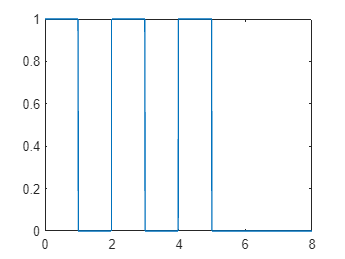


plot(t, f)


% Impulsos
impulsos = impulso_unitario(t, 0) + impulso_unitario(t, 4) + impulso_unitario(t, 8);

convolucion = conv(f, impulsos)

convolucion =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


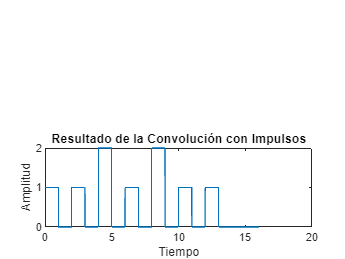


subplot(2, 1, 2);
plot(0:0.01:16, convolucion);
title('Resultado de la Convolución con Impulsos');
xlabel('Tiempo');
ylabel('Amplitud');

function impulso = impulso_unitario(t, t0)
    impulso = zeros(size(t));
    impulso(t == t0) = 1; % Valor 1 en el punto t0
end